clear all
clc

Q1

% Load the data
data = readtable('realgdpgrowth.xlsx');

% Extract the 'pdi' series
pdi = data(:,["pdi","date"]);

% Remove missing values if necessary
pdi = rmmissing(pdi);
%discard first 10 observations

% Determine the maximum AR order to consider
maxOrder = 10;

est=(data.date>=datetime(1950,4,1));
X1=lagmatrix(pdi.pdi,1);
mdl1=fitlm(X1(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,1)=mdl1.ModelCriterion.AIC;

X2=lagmatrix(pdi.pdi,1:2);
mdl2=fitlm(X2(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,2)=mdl2.ModelCriterion.AIC;

X3=lagmatrix(pdi.pdi,1:3);
mdl3=fitlm(X3(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,3)=mdl3.ModelCriterion.AIC;

X4=lagmatrix(pdi.pdi,1:4);
mdl4=fitlm(X4(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,4)=mdl4.ModelCriterion.AIC;

X5=lagmatrix(pdi.pdi,1:5);
mdl5=fitlm(X5(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,5)=mdl5.ModelCriterion.AIC;

X6=lagmatrix(pdi.pdi,1:6);
mdl6=fitlm(X6(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,6)=mdl6.ModelCriterion.AIC;

X7=lagmatrix(pdi.pdi,1:7);
mdl7=fitlm(X7(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,7)=mdl7.ModelCriterion.AIC;

X8=lagmatrix(pdi.pdi,1:8);
mdl8=fitlm(X8(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,8)=mdl8.ModelCriterion.AIC;

X9=lagmatrix(pdi.pdi,1:9);
mdl9=fitlm(X9(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,9)=mdl9.ModelCriterion.AIC;

X10=lagmatrix(pdi.pdi,1:10);
mdl10=fitlm(X10(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,10)=mdl10.ModelCriterion.AIC;

X11=lagmatrix(pdi.pdi,1:11);
mdl11=fitlm(X11(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,11)=mdl11.ModelCriterion.AIC;

X12=lagmatrix(pdi.pdi,1:12);
mdl12=fitlm(X12(est,:),pdi.pdi(est)); %reg X on Y
AIC(1,12)=mdl12.ModelCriterion.AIC;
disp(AIC);

   1.0e+03 *

    2.5625    2.5627    2.5647    2.5560    2.5573    2.5564    2.5551    2.5571    2.5591    2.5576    2.5593    2.5589



[~, bestOrder] = min(AIC);
disp(bestOrder);

     7



Since AR(7) has the least AIC value, we select AR(7) model. 

Q2(a)

% Load Data
data2 = readtable('s&p.csv'); 

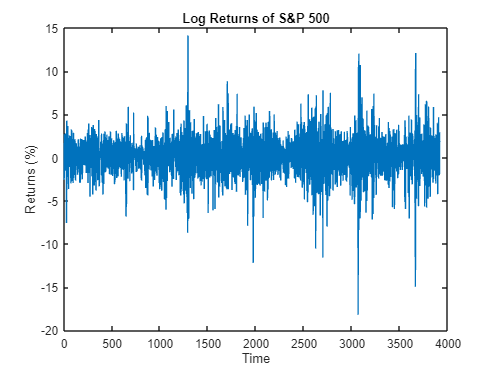

adjClose = data2.adjClose;    % Extract adjusted close prices column

%% Part (a): Transform into returns and plot
% Compute log returns: r_t = 100 * (s_t - s_{t-1}) / s_{t-1}
returns = 100 * diff(adjClose) ./ adjClose(1:end-1);

% Plot Returns
figure;
plot(returns);
title('Log Returns of S&P 500');
xlabel('Time');
ylabel('Returns (%)');

%% Part (b)-1: Test for Serial Correlation Using Matrix Operations
% Construct the AR(2) Model: r_t = α + β1*r_{t-1} + β2*r_{t-2} + ε_t
OLSmdl= fitlm(lagmatrix(returns,1:2),returns)

OLSmdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)      0.17353    0.033859      5.125    3.1195e-07
    x1             -0.040104     0.01598    -2.5096      0.012127
    x2              0.036283     0.01598     2.2705       0.02323


Number of observations: 3914, Error degrees of freedom: 3911
Root Mean Squared Error: 2.1
R-squared: 0.00305,  Adjusted R-Squared: 0.00254
F-statistic vs. constant model: 5.98, p-value = 0.00256

[EstCov,se,coeff]=hac(OLSmdl,'display','off');
R=[0,1,0;0,0,1];
[h,pValue,stat,cValue]=waldtest(coeff(2:3,1),R,EstCov)

h = logical
   1


pValue = 0.0190

stat = 7.9214

cValue = 5.9915

%% Part (b)-2 Compute Heteroscedasticity-Consistent Wald Test
OLSmdl2= fitlm(lagmatrix(returns,1:2),returns) %actually no need for 2 model since coeffients for homo and hetero are same

OLSmdl2 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)      0.17353    0.033859      5.125    3.1195e-07
    x1             -0.040104     0.01598    -2.5096      0.012127
    x2              0.036283     0.01598     2.2705       0.02323


Number of observations: 3914, Error degrees of freedom: 3911
Root Mean Squared Error: 2.1
R-squared: 0.00305,  Adjusted R-Squared: 0.00254
F-statistic vs. constant model: 5.98, p-value = 0.00256

[EstCov,se,coeff]=hac(OLSmdl2,'display','off',Type="HC");
R=[0,1,0;0,0,1];
[h,pValue,stat,cValue]=waldtest(coeff(2:3,1),R,EstCov)

h = logical
   0


pValue = 0.0716

stat = 5.2738

cValue = 5.9915

Part (c): Compare and Interpret Results

We found that classical Wald test does not reject null hypothesis but the heteroscedasticity-consistent Wald test reject the null hypothesis that 2 coefficient are 0. I think the heteroscedasticity-consistent Wald tests is appropriate since by looking at the residual, we find that they do not follow a homoskedatistic pattern. Commonly, stock market datas are likely to be heteroskedatistic. Heteroskedatistic test is also prefered since they have different result, which means there are some hetero pattern.

Q3(a)

data = readtable('realgdpgrowth.xlsx');  % Load the dataset
exports = data.exports;  % Extract the export growth rate column
X=lagmatrix(exports,1:4);
model = fitlm(X, exports);


%%Classical Standard Errors
%classical_SE = model.Coefficients.SE; 
%disp(classical_SE);
disp(model.Coefficients);

                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)       6.2253      1.1942      5.2131    3.4578e-07
    x1              -0.12286    0.057361     -2.1418      0.033012
    x2               0.11178    0.056986      1.9616      0.050735
    x3                0.0552    0.056672     0.97402       0.33083
    x4             -0.051555    0.056496    -0.91253       0.36222



%% Compute Robust (Heteroscedasticity-Consistent) Standard Errors
%Robust_Se
[EstCov,se,coeff]=hac(model,'display','off',Type="HC");
disp(se);

    1.4695
    0.1004
    0.0650
    0.0667
    0.0524



Q3(b)

Yes, two SE are different. And the result follow the general pattern that hetero SE is larger than homo SE. 